clc;
clear;

inpFile = 'C:\Users\Hp\Desktop\GROUP4_EPANET_MATLAB_Assignment\GROUP4_NETWORK.inp';
d = epanet(inpFile);

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "C:\Users\Hp\Desktop\GROUP4_EPANET_MATLAB_Assignment\GROUP4_NETWORK.inp"...
Input File "C:\Users\Hp\Desktop\GROUP4_EPANET_MATLAB_Assignment\GROUP4_NETWORK.inp" loaded successfully.



disp('Network loaded successfully');

Network loaded successfully


disp('Number of nodes:');

Number of nodes:


disp(d.getNodeCount);

   7



disp('Number of Links:');

Number of Links:


disp(d.getLinkCount);

   7



disp(d.getLinkVelocity());

     0     0     0     0     0     0     0




%Load a network.
d = epanet('GROUP4_NETWORK.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "GROUP4_NETWORK.inp"...
Input File "GROUP4_NETWORK.inp" loaded successfully.



disp('Add a CV pipe')

Add a CV pipe


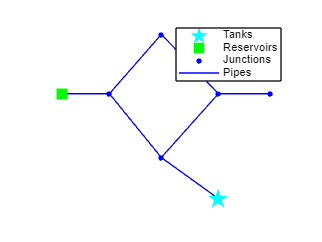

%Plot network components.
d.plot;

%Get from and to nodes for add cv pipe.
fromNode = d.getNodeNameID{2};
toNode = d.getNodeNameID{6};
node_index = d.addLinkPipeCV('CVPipe',fromNode,toNode);
%Plot new network with changes.
d.plot('links','yes');

%Unload library.
d.unload

EPANET Class is unloaded



start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


d=epanet('GROUP4_NETWORK.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "GROUP4_NETWORK.inp"...
Input File "GROUP4_NETWORK.inp" loaded successfully.


hydstep = d.getTimeHydraulicStep;
duration = d.getTimeSimulationDuration;
pipe_count = d.getLinkPipeCount;
pipeIDs = d.getLinkPipeNameID;
spsmax = max(cellfun('length',pipeIDs));
hrs = duration/3600;
hours = 0:hrs;
step = 0:hydstep/60:55; %step 30min
i=1; Time = cell(hrs,1);

for u=1:hrs
    % Create random status for pipes every hour.
    status_code = round(rand(1,pipe_count));
    status(find(status_code)) = {'Open  '};
    status(find(~status_code)) = {'Closed'};
    for j=1:length(step)
        for np=1:pipe_count
            Time{i} = sprintf('%03d:%02d:00',hours(u),30);
            sps = blanks(spsmax-length(pipeIDs{np}));
            Controls(i,: ) = ['LINK ',pipeIDs{np}, sps,' ', status{np}, ' AT CLOCKTIME ',Time{i}];
            d.addControls(['LINK ',pipeIDs{np}, sps,' ', status{np}, ' AT CLOCKTIME ',Time{i}]);
            i=i+1;
        end
    end
end

disp('Create random status')

Create random status


figure;
RES = d.getComputedHydraulicTimeSeries('flow');
plot(RES.Flow);
title('Change status of pipes every hour');
xlabel('Time (hours)');

d.unload;

EPANET Class is unloaded



start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('GROUP4_NETWORK.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "GROUP4_NETWORK.inp"...
Input File "GROUP4_NETWORK.inp" loaded successfully.


hyd_res = d.getComputedTimeSeries

hyd_res = struct with fields:
              Time: [2×1 double]
          Pressure: [2×7 single]
            Demand: [2×7 single]
              Head: [2×7 single]
       NodeQuality: [2×7 single]
              Flow: [2×7 single]
          Velocity: [2×7 single]
          HeadLoss: [2×7 single]
            Status: [2×7 single]
           Setting: [2×7 single]
      ReactionRate: [2×7 single]
    FrictionFactor: [2×7 single]
       LinkQuality: [2×7 single]
      EnergyReport: [1×1 struct]
         StatusStr: {2×7 cell}


times = hyd_res.Time;  % get time stamps
color = 'g';  % choose color
nodenameid = d.getNodeNameID;  % get node IDs
linknameid = d.getLinkNameID;  % get link IDs
nodesconnlinks = d.getNodesConnectingLinksID;  % get node connectivity
nodecoords = d.getNodeCoordinates;  % get node coordinates
x = nodecoords{1};
y = nodecoords{2};
min_coorx = min(x);
min_coory = min(y);
max_coorx = max(x);
max_coory = max(y);
xsenoff = (max_coorx - min_coorx) * 0.075;
ysenoff = (max_coory - min_coory) * 0.03;
fig = d.plot('legend', 'hide');
format long g
time_step = 2;
flow = hyd_res.Flow(time_step,:);
fontweight = 'bold';
fontsize = 10;
for i = d.getLinkIndex
    value = flow(i);    
    FromNode=strfind(strcmp(nodesconnlinks(i, 1), nodenameid), 1);
    ToNode=strfind(strcmp(nodesconnlinks(i, 2), nodenameid), 1);

    if FromNode
        x1 = double(nodecoords{1}(FromNode));
        y1 = double(nodecoords{2}(FromNode));
    end
    if ToNode
        x2 = double(nodecoords{1}(ToNode));
        y2 = double(nodecoords{2}(ToNode));
    end
    F = line([x1 nodecoords{3}{i} x2], [y1 nodecoords{4}{i} y2], 'LineWidth', 1, 'Color', color, 'Parent', fig);
    text((x1+x2)/2-xsenoff, (y1+y2)/2+ysenoff, num2str(value, '%.5f'), 'FontWeight', fontweight, 'Fontsize', fontsize, 'color', color)
end
time_step = 2;
pressure = hyd_res.Pressure(time_step,:);
ysenoff = (max_coory - min_coory) * (-0.04);
color = 'b';
fontweight = 'bold';
fontsize = 10;
for i = d.getNodeIndex
    value = pressure(i);
    coor = d.getNodeCoordinates(i);
    x = coor(1); 
    y = coor(2);
    P = plot(x, y, 'o', 'LineWidth', 2, 'MarkerEdgeColor', color, 'MarkerFaceColor', color, 'MarkerSize', 5);
    text(x-xsenoff, y+ysenoff, num2str(value, '%.2f'), 'FontWeight', fontweight, 'Fontsize', fontsize, 'color', color)
end
legend([F,P], {'Flows', 'Pressures'})

d.unload

EPANET Class is unloaded



start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('C:\Users\Hp\Desktop\GROUP4_EPANET_MATLAB_Assignment\GROUP4_NETWORK.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "C:\Users\Hp\Desktop\GROUP4_EPANET_MATLAB_Assignment\GROUP4_NETWORK.inp"...
Input File "C:\Users\Hp\Desktop\GROUP4_EPANET_MATLAB_Assignment\GROUP4_NETWORK.inp" loaded successfully.


d.setQualityType('Chlorine', 'mg/L');
initialQuality = 0.6;
nodeIndex = [6 7];
d.setNodeInitialQuality(nodeIndex,[0.6 0.6]);
etstep = 3600;
d.setTimeReportingStep(etstep);
d.setTimeHydraulicStep(etstep);
d.setTimeQualityStep(etstep);
d.openHydraulicAnalysis;
d.openQualityAnalysis;
d.initializeHydraulicAnalysis(0);
d.initializeQualityAnalysis(d.ToolkitConstants.EN_NOSAVE);

tstep = 1;
T = []; P = []; F = []; QN = []; QL = [];
while (tstep>0)
    t = d.runHydraulicAnalysis;
    qt = d.runQualityAnalysis;

    P = [P; d.getNodePressure];
    F = [F; d.getLinkFlows];
    
    QN = [QN; d.getNodeActualQuality];
    QL = [QL; d.getLinkActualQuality];
    T = [T; t];

    tstep = d.nextHydraulicAnalysisStep;
    qtstep = d.nextQualityAnalysisStep;
end
d.closeQualityAnalysis;
d.closeHydraulicAnalysis;

P

P = 2×7 single matrix
        85.05625        79.70249        74.27573         75.0732        76.03307               0              10
        85.22809        79.98879         74.7999        75.48846        76.44833               0        11.09808


F

F =           58.3020210266113          20.1061134338379          37.1959075927734          19.3061122894287         -17.6061134338379         0.699999988079071          53.9020233154297
          57.1989250183105          19.7326278686523          36.4663009643555          18.9326267242432         -17.2326278686523         0.699999988079071          52.7989273071289


QN

QN = 2×7 single matrix
               0               0               0               0               0             0.6             0.6
       0.5775479       0.5352467       0.5201935       0.4876146       0.1076805             0.6       0.5922619


QL

QL =                          0                         0                         0                         0                         0                         0         0.600000023841858
         0.600000023841858         0.577547907829285         0.577547907829285         0.535246670246124          0.48761460185051          0.48761460185051         0.520193517208099


d.unload;

EPANET Class is unloaded



start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('GROUP4_NETWORK.inp', 'loadfile');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "GROUP4_NETWORK.inp"...
Input File "GROUP4_NETWORK.inp" loaded successfully.


hyd_res = d.getComputedHydraulicTimeSeries('time', 'pressure', 'flow', 'velocity');
hrs_time = hyd_res.Time/3600;
node_indices = [1, 3, 5];
node_names = d.getNodeNameID(node_indices);
units = d.getUnits;
for i=node_indices
    figure;
    plot(hrs_time, hyd_res .Pressure(:,i));
    title(['Pressure for the node id "', d.getNodeNameID{i},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Pressure (', units.NodePressureUnits,')'])
end

link_indices = [4, 6, 7];
link_names = d.getLinkNameID;(link_indices);
for i=link_indices
    figure;
    plot(hrs_time, hyd_res.Velocity(:,i));
    title(['Velocity for the link id "', d.getLinkNameID{i},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Velocity (', units.LinkVelocityUnits,')'])
end

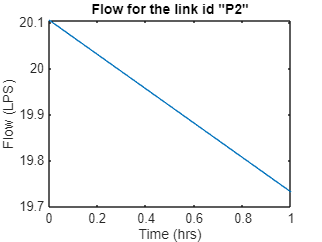

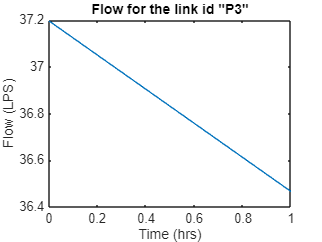

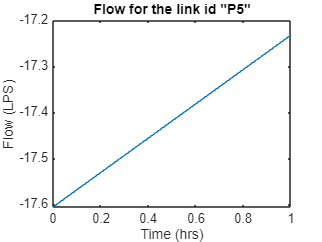

link_indices = [2, 3, 5];
for i=link_indices
    figure;
    plot(hrs_time, hyd_res.Flow(:,i));
    title(['Flow for the link id "', d.getLinkNameID{i},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Flow (', units.LinkFlowUnits,')'])
end

d.unload

EPANET Class is unloaded



start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('GROUP4_NETWORK.inp') ; 

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "GROUP4_NETWORK.inp"...
Input File "GROUP4_NETWORK.inp" loaded successfully.


ans =   Axes with properties:

             XLim: [-0.1 9.5]
             YLim: [0.04 4.36]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


d.plot

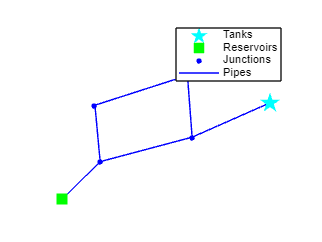

ans =   Axes with properties:

             XLim: [1.10081415712958 7.09104427157463]
             YLim: [0.44833395016046 8.76217782649107]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


theta = pi/3; %60 degrees
x = d.getNodeCoordinates{1}';
y = d.getNodeCoordinates{2}';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ****
v = [x;y];
x_center = x(1);
y_center = y(1);
center = repmat([x_center; y_center], 1, length(x));
% theta = pi/3;       % pi/3 radians = 60 degrees
R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
v = [v(1:7,1),v(8:14,1)];
s = v - center';     % Shift points in the plane so that the center of rotation is at the origin.
so = R*s';           % Apply the rotation about the origin.
vo = so + center;    % Shift again so the origin goes back to the desired center of rotation.
% this can be done in one line as:
% vo = R*(v - center) + center
x_new = vo(1,:);
y_new = vo(2,:);
% ****
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for i=1:d.NodeCount
    d.setNodeCoordinates(i, [x_new(i) y_new(i)]);
end
d.plot

d.saveInputFile('rotated.inp');

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('GROUP4_NETWORK.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "GROUP4_NETWORK.inp"...
Input File "GROUP4_NETWORK.inp" loaded successfully.


disp('Add CV PIPE with Bin Functions addBinJunction')

Add CV PIPE with Bin Functions addBinJunction


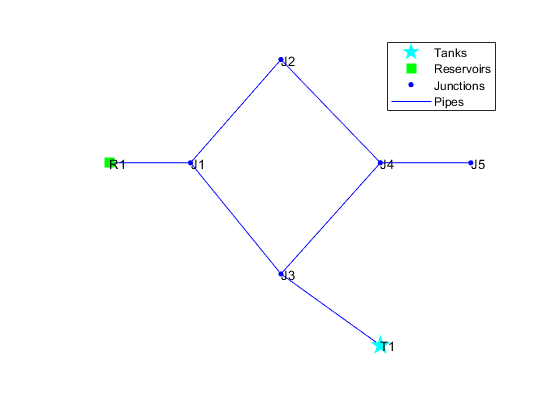

d.Binplot('nodes','yes');
%  addBinJunction
%  arguments: newNodeID,X,Y,ToNodeID,newElevation,newBaseDemand,newDemandPattern,newPipeID,
%  newLength,newDiameter,newRoughness,Code
%  Add Junction + CV pipe.
newID='J1';
[x,y]=ginput(1);

ToNodeID='10'; 
newElevation=500; % ft
newBaseDemand=0;
newDemandPattern='1';
newPipeID='CV-P2';
newLength=1000; % ft
newDiameter=10; % in
newRoughness=100;
patternCategoryID = '';
quality = 0.5;

Code='CVPIPE';'CVPIPE', 'PIPE', 'PUMP', 'PRV', 'PSV', 'PBV', 'FCV', 'TCV', 'GPV'

ans = 'CVPIPE'

ans = 'PIPE'

ans = 'PUMP'

ans = 'PRV'

ans = 'PSV'

ans = 'PBV'

ans = 'FCV'

ans = 'TCV'

ans = 'GPV'


[node_index, link_index] = d.addBinNodeJunction(newID, [x, y], newElevation, newBaseDemand, newDemandPattern, patternCategoryID, quality,...
      {'PIPE', {newPipeID}, newID, ToNodeID, newLength, newDiameter, newRoughness}); 

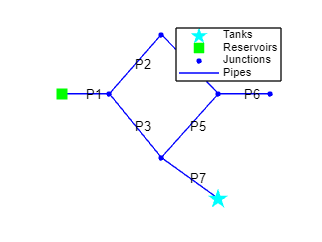

d.plot('links','yes');

d.unload

EPANET Class is unloaded
